# Performance evaluation: ROC curves

You are working on a project to classify between cancerous (malignant) and healthy (benign) biopsies. Your colleague has shared two trained classifiers with you and some previously unseen testing data. You can assume the data has been properly prepared:

clear all;
load('classifiers.mat', 'm_nb', 'm_dt', 'test_examples', 'test_labels');

Your task is to analyse the True Positive Rate (TPR) and False Positive Rate (FPR) for each classifier in order to make a decision about which one is performing best.

Marks are available for:

- Using each classifier to predict labels and associated likelihood scores for the test data [4 marks]

- Computing the TPR for each classifier, taking "Malignant" as the positive class [3 marks]

- Computing the FPR for each classifier, taking "Malignant" as the positive class [3 marks]

- Generating a Receiver Operating Characteristic (ROC) curve for each classifier, taking "Malignant" as the positive class, and plotting them together on a single graph with a legend and labelled axes [4 marks]

- Deciding on the best classifier based on a sensible quantitative comparison between the ROC curves [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:

% predicted labels and label likelihood stored in predictions array and scores vector
[predictions, scores] = predict(m_nb, test_examples)

predictions = 142×1 categorical array
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Malignant 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Malignant 


scores =     0.0000    1.0000
    0.0000    1.0000
    1.0000    0.0000
    1.0000    0.0000
    0.0000    1.0000
    0.0000    1.0000
    1.0000    0.0000
    1.0000    0.0000
    0.0000    1.0000
    1.0000    0.0000


[nb_c, order] = confusionmat(test_labels, predictions) % nb confusion matrix and order of labels

nb_c =     83     2
     4    53


order = 2×1 categorical array
     Benign 
     Malignant 



nb_tpr = nb_c(2, 2) / (nb_c(2, 2) + nb_c(2, 1)) % TPR of NB classifier with 'Malignant' as positive class

nb_tpr = 0.9298

nb_fpr = nb_c(1, 2) / (nb_c(1, 2) + nb_c(1, 1)) % FPR of NB classifier with 'Malignant' as positive class

nb_fpr = 0.0235


% ROC curve for NB classifier using Malignant label as positive class
[x1, y1] = perfcurve(test_labels, scores(:, 2), order(2, 1));

% predicted labels and label likelihood stored in predictions array and scores vector
[predictions, scores] = predict(m_dt, test_examples);

% confusion matrix and order of labels
[dt_c, order] = confusionmat(test_labels, predictions) % dt confusion matrix and order of labels

dt_c =     82     3
     5    52


order = 2×1 categorical array
     Benign 
     Malignant 


dt_tpr = dt_c(2, 2) / (dt_c(2, 2) + dt_c(2, 1)) % TPR of DT classifier with 'Malignant' as positive class

dt_tpr = 0.9123

dt_fpr = dt_c(1, 2) / (dt_c(1, 2) + dt_c(1, 1)) % FPR of DT classifier with 'Malignant' as positive class

dt_fpr = 0.0353

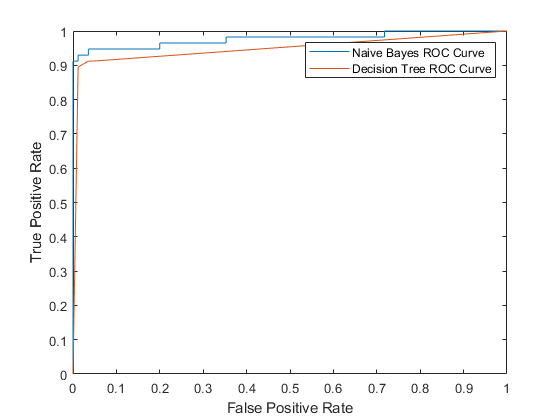


% ROC curve for DT classifier using Malignant label as positive class
[x2, y2] = perfcurve(test_labels, scores(:, 2), order(2, 1));

plot(x1, y1, x2, y2) % plot both classifiers' ROC curves
xlabel("False Positive Rate") % x title
ylabel("True Positive Rate") % y title
legend("Naive Bayes ROC Curve", "Decision Tree ROC Curve") % legend titles

% NAIVE BAYES CLASSIFIER IS BEST BASED ON ROC CURVE